# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 3.4.1 Range Profile - Point Targets

## Calculate the range profile from the matched filter output

clear
clc

% Set up the time array (s)
t = linspace(0, 10, 1e4);

% Set the time delay to the target (s)
t0 = 3.5;

% Set the chirp slope
beta = 1.5;

% Set the starting frequency (Hz)
f0 = 0;

% Calculate the transmitted and received waveforms
st = exp(1j * pi * beta * t.^2);
sr = exp(1j * 2 * pi * (f0 *(t - t0) + 0.5 * beta * (t - t0).^2));

% Perform matched filtering
H = fft(conj(st));
S = fft(sr);
so = (ifft(S .* H));


## Plot the results

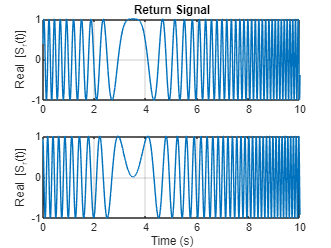

% The return signal real and imaginary components
figure;
subplot(211);
plot(t, real(sr));
title('Return Signal')
ylabel('Real [S_r(t)]')
grid on

subplot(212);
plot(t, imag(sr));
xlabel('Time (s)');
ylabel('Real [S_r(t)]')
grid on

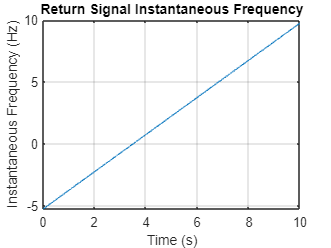


% The instantaneous frequency of the return signal
figure;
plot(t, f0 + beta*(t - t0));
title('Return Signal Instantaneous Frequency')
xlabel('Time (s)')
ylabel('Instantaneous Frequency (Hz)')
grid on

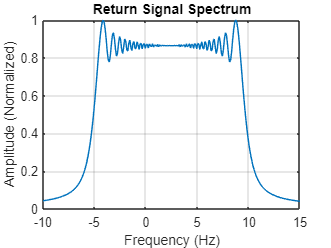


% The spectrum of the return signal
figure;
sf = abs(fft(sr));
sf = sf / max(sf);
fmax = 1 / (2 * (t(2) - t(1)));
f = linspace(-fmax, fmax, 1e4);
plot(f, fftshift(sf))
grid on
title('Return Signal Spectrum')
xlabel('Frequency (Hz)')
ylabel('Amplitude (Normalized)')
xlim([-10, 15]);
yticks([0, 0.2, 0.4, 0.6, .8, 1]);

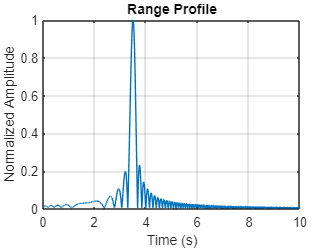


% The range profile
figure;
plot(t, abs(so)/max(abs(so)));
grid on
title('Range Profile')
xlabel('Time (s)')
ylabel('Normalized Amplitude')